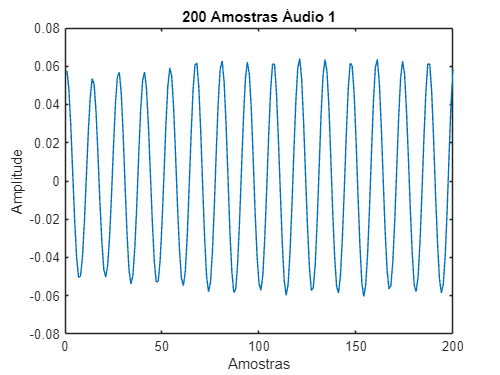

% Ler o arquivo WAV
[data1, samplerate1] = audioread('Assovio.wav');
[data2, samplerate2] = audioread('Testando123.wav');

% Exibir a taxa de amostragem e as dimensões dos dados
samplerate1;
size(data1);
samplerate2;
size(data2);


%plot(data1);
%title('Sinal de Áudio 1');
%xlabel('Amostras');
%ylabel('Amplitude');

%figure
%plot(data2);
%title('Sinal de Áudio 2');
%xlabel('Amostras');
%ylabel('Amplitude');


% Reproduzir o áudio
%sound(data1, samplerate);
%sound(data2, samplerate);

%1)
%a) Plote 200 amostras mais ou menos no centro de cada sinal em gráficos diferentes.
plot(data1(16001:16200));
title('200 Amostras Áudio 1');
xlabel('Amostras');
ylabel('Amplitude');

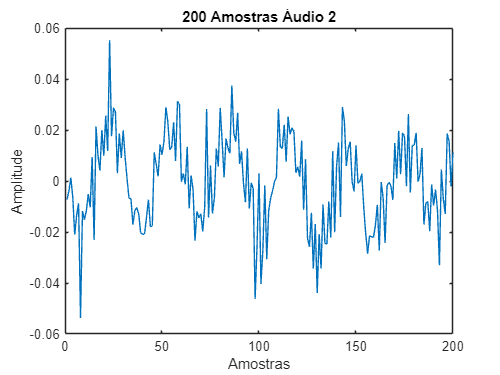

figure

plot(data2(16001:16200));
title('200 Amostras Áudio 2');
xlabel('Amostras');
ylabel('Amplitude');

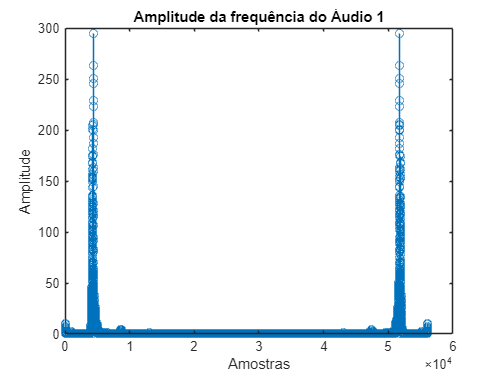

figure

%b) Plote a amplitude do espectro de frequências de cada sinal (valor absoluto da 
% fft modo stem) em gráficos separados.
Y1=fft(data1);
stem(abs(Y1))
title('Amplitude da frequência do Áudio 1');
xlabel('Amostras');
ylabel('Amplitude');

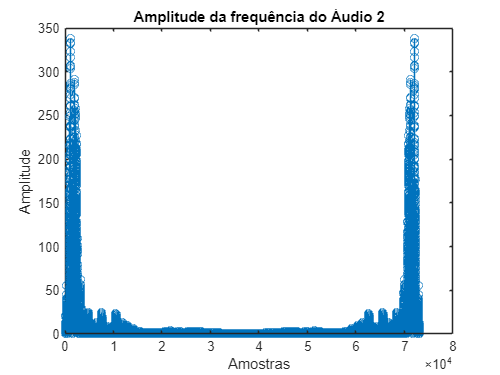

figure

Y2=fft(data2);
stem(abs(Y2))
title('Amplitude da frequência do Áudio 2');
xlabel('Amostras');
ylabel('Amplitude');

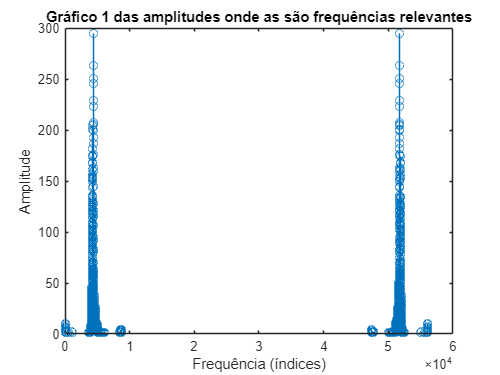

figure

%c) Plote a amplitude da região do espectro onde as frequências são mais 
%relevantes (valor absoluto da fft dos maiores valores).
amplitude1 = abs(Y1);
limite1 = prctile(amplitude1, 95);
indices_maiores1 = find(amplitude1 > limite1);
stem(indices_maiores1, amplitude1(indices_maiores1));
title('Gráfico 1 das amplitudes onde as são frequências relevantes');
xlabel('Frequência (índices)');
ylabel('Amplitude');

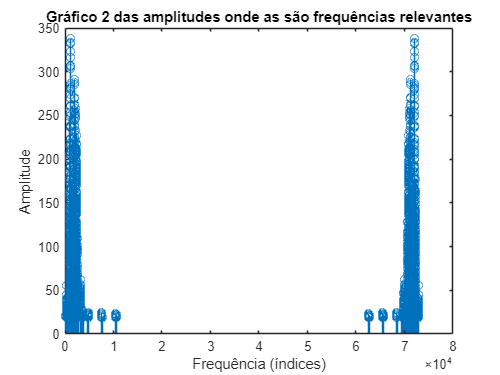

figure;
%amplitude1 = abs(Y1);
%num_freq1 = 150;
%[~, ind_maiores1] = maxk(amplitude1, num_freq1);
%stem(ind_maiores1, amplitude1(ind_maiores1));
%title('Gráfico 1 das amplitudes onde as são frequências relevantes');
%xlabel('Frequência (índices)');
%ylabel('Amplitude');


amplitude2 = abs(Y2);
limite2 = prctile(amplitude2, 95);
indices_maiores2 = find(amplitude2 > limite2);
stem(indices_maiores2, amplitude2(indices_maiores2));
title('Gráfico 2 das amplitudes onde as são frequências relevantes');
xlabel('Frequência (índices)');
ylabel('Amplitude');

figure;


%d)


%2)
%a)Crie o sinal y1 com a soma dos dois áudios (se precisar aumente o audio menor 
% com zeros no final, you diminua áudio maior removendo amostras). 
% Gere um .wav e escute o sinal y1.



























